# DNA Sequencing

# Nanopore Sequencing

## Input Nanopore Sequencing Data (FASTQ File)

fastqinfo('lambda_nanopore.fastq')

ans = struct with fields:
           Filename: 'lambda_nanopore.fastq'
           FilePath: 'C:\Users\kabil\OneDrive - Drexel University\Academic\3 - Pre-Junior\1 - Fall Quarter\BMES 375\bmes375.TonyOkeke.tko35\HW8'
        FileModDate: '14-Oct-2021 22:56:12'
           FileSize: 10926131
    NumberOfEntries: 947

reads = fastqread('lambda_nanopore.fastq')

reads = 1×947 struct array with fields:
    Header
    Sequence
    Quality

## Read Length Distribution of All Sequencing Reads

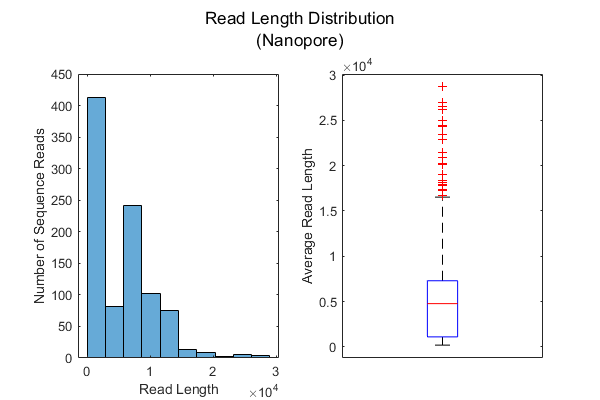

seqs_nano = {reads.Sequence}; % convert to cell array
readLen_nano = cellfun(@length, seqs_nano); % calculate read length

% Visualize results
figure('Position', [0 0 600 400]), sgtitle({'Read Length Distribution', '(Nanopore)'});
subplot(1,2,1), histogram(readLen_nano, 10);
xlabel('Read Length'), ylabel('Number of Sequence Reads');
subplot(1,2,2), boxplot(readLen_nano), ylabel('Average Read Length'), xticks([]);

**Caption: **The figure shows the distribution of sequence read lengths from the nanopore sequencing run. On the left is a histogram showing the frequency distribution of read lengths. On the right is a boxplot showing the median, upper and lower quartiles, and outliers of average sequence read length.

**Conclusion: **The average read length for the nanopore tends to be around $0.5\times10^4$. Although, there are some outliers with as high as $2.5\times10^4$ reads.

## Quality Score Distribution per Sequencing Read

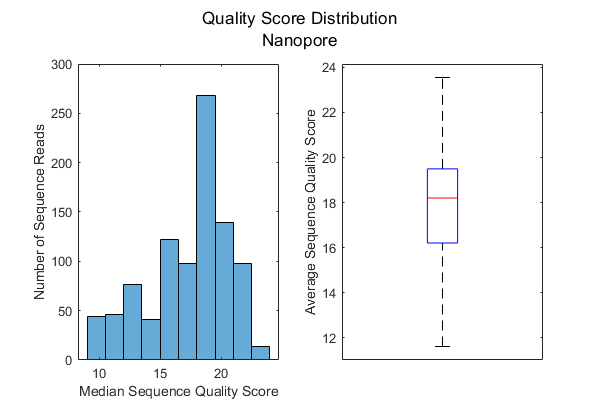

seqQ_nano = {reads.Quality}; % ASCII format
% Convert ascii to digits
seqQS_nano = cellfun(@(x) double(x) - 33, seqQ_nano, 'UniformOutput', false);

% Average, Median & Standard Deviation
avgQS_nano = cellfun(@mean, seqQS_nano);
medQS_nano = cellfun(@median, seqQS_nano);
stdQS_nano = cellfun(@std, seqQS_nano);

% Plot Distribution of Median and Average Quality
figure('Position', [0 0 600 400]), sgtitle({'Quality Score Distribution', 'Nanopore'});
subplot(1,2,1), histogram(medQS_nano, 10);
xlabel('Median Sequence Quality Score'), ylabel('Number of Sequence Reads');
subplot(1,2,2), boxplot(avgQS_nano), ylabel('Average Sequence Quality Score'), xticks([]);

**Caption: **The figure shows the distribution of sequence quality scores from the nanopore sequencing run. On the left is a histogram showing the frequency distribution of quality scores. On the right is a boxplot showing the median, upper and lower quartiles, and outliers of average sequence quality score.

**Conclusion:** The average quality score for the nanopore tends to be around 18 and seems to follow a slightly skewed normal distribution.

## GC Content Histogram per Sequence Read

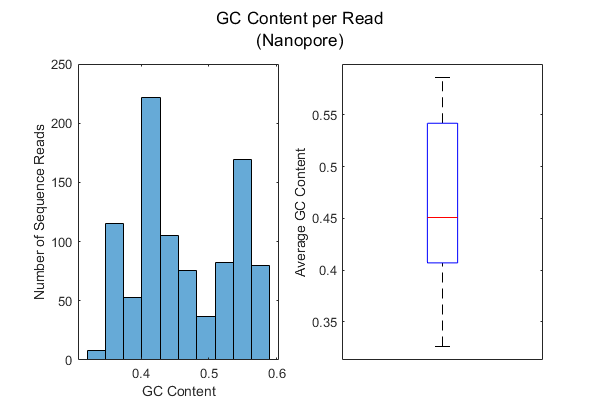

% Determine G and C content of reads
G_nano = cellfun(@(x) numel(strfind(x, 'G')), seqs_nano);
C_nano = cellfun(@(x) numel(strfind(x, 'C')), seqs_nano);

% Determine the GC content
GC_nano = (G_nano + C_nano) ./ readLen_nano;

% Visualize results
figure('Position', [0 0 600 400]), sgtitle({'GC Content per Read', '(Nanopore)'});
subplot(1,2,1), histogram(GC_nano, 10);
xlabel('GC Content'), ylabel('Number of Sequence Reads');
subplot(1,2,2), boxplot(GC_nano), ylabel('Average GC Content'), xticks([]);

**Caption: **The figure shows the distribution of GC content from the nanopore sequencing run. On the left is a histogram showing the frequency distribution of GC content. On the right is a boxplot showing the median, upper and lower quartiles, and outliers of average GC content.

**Conclusion:** The average GC content for the nanopore tends to be about 45%.

# Illumina Sequencing

## Input Illumina Sequencing Data (FASTQ File)

fastqinfo('lambda_illum.fastq')

ans = struct with fields:
           Filename: 'lambda_illum.fastq'
           FilePath: 'C:\Users\kabil\OneDrive - Drexel University\Academic\3 - Pre-Junior\1 - Fall Quarter\BMES 375\bmes375.TonyOkeke.tko35\HW8'
        FileModDate: '14-Oct-2021 22:56:55'
           FileSize: 311925841
    NumberOfEntries: 792838

reads = fastqread('lambda_illum.fastq')

reads = 1×792838 struct array with fields:
    Header
    Sequence
    Quality

## Read Length Distribution of All Sequencing Reads

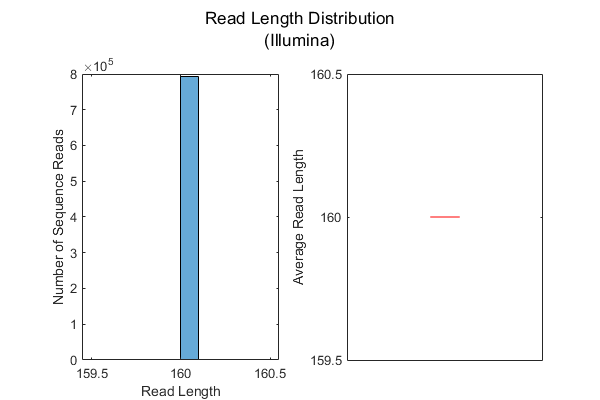

seqs_ilum = {reads.Sequence};
readLen_ilum = cellfun(@length, seqs_ilum);

% Visualize results
figure('Position', [0 0 600 400]), sgtitle({'Read Length Distribution', '(Illumina)'});
subplot(1,2,1), histogram(readLen_ilum, 10);
xlabel('Read Length'), ylabel('Number of Sequence Reads');
subplot(1,2,2), boxplot(readLen_ilum), ylabel('Average Read Length'), xticks([]);

**Caption: **The figure shows the distribution of sequence read lengths from the Illumina sequencing run. On the left is a histogram showing the frequency distribution of read lengths. On the right is a boxplot showing the median, upper and lower quartiles, and outliers of average sequence read length.

**Conclusion: **The read length is consistent at 160 bps for all samples.

## Quality Score Distribution per Sequencing Read

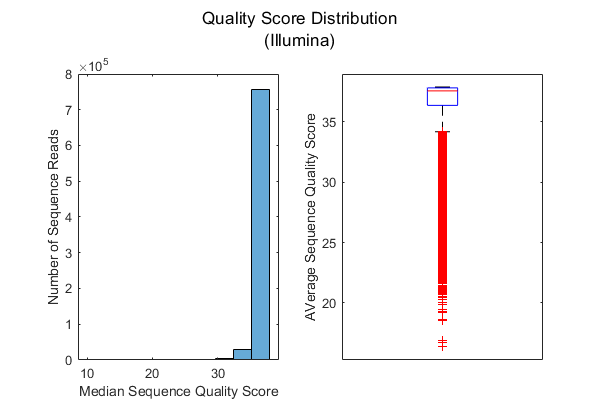

seqQ_ilum = {reads.Quality}; % ASCII format
seqQS_ilum = cellfun(@(x) double(x) - 33, seqQ_ilum, 'UniformOutput', false);

% Average, Median & Standard Deviation
avgQS_ilum = cellfun(@mean, seqQS_ilum);
medQS_ilum = cellfun(@median, seqQS_ilum);
stdQS_ilum = cellfun(@std, seqQS_ilum);

% Plot Distribution of Median and Average Quality
figure('Position', [0 0 600 400]), sgtitle({'Quality Score Distribution', '(Illumina)'});
subplot(1,2,1), histogram(medQS_ilum, 10);
xlabel('Median Sequence Quality Score'), ylabel('Number of Sequence Reads');
subplot(1,2,2), boxplot(avgQS_ilum), ylabel('AVerage Sequence Quality Score'), xticks([]);

**Caption: **The figure shows the distribution of sequence quality scores from the Illumina sequencing run. On the left is a histogram showing the frequency distribution of quality scores. On the right is a boxplot showing the median, upper and lower quartiles, and outliers of average sequence quality score.

**Conclusion:** The quality scores remain relatively consistent at 36. However, there are several outliers with quality scores as low as 20.

## GC Content Histogram per Sequence Read

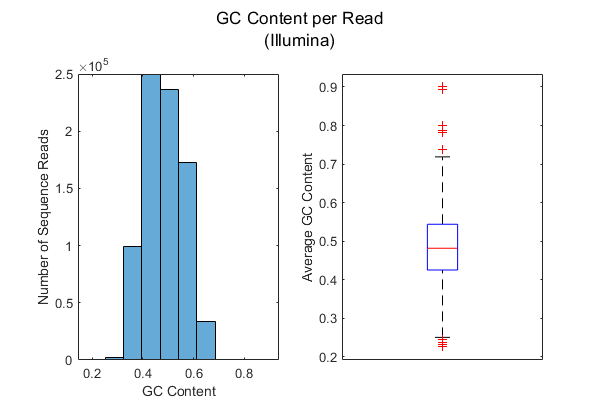

% Determine G and C content of reads
G_ilum = cellfun(@(x) numel(strfind(x, 'G')), seqs_ilum);
C_ilum = cellfun(@(x) numel(strfind(x, 'C')), seqs_ilum);

% Determine the GC content
GC_ilum = (G_ilum + C_ilum) ./ readLen_ilum;

% Visualize results
figure('Position', [0 0 600 400]), sgtitle({'GC Content per Read', '(Illumina)'});
subplot(1,2,1), histogram(GC_ilum, 10);
xlabel('GC Content'), ylabel('Number of Sequence Reads');
subplot(1,2,2), boxplot(GC_ilum), ylabel('Average GC Content'), xticks([]);

**Caption: **The figure shows the distribution of GC content from the Illumina sequencing run. On the left is a histogram showing the frequency distribution of GC content. On the right is a boxplot showing the median, upper and lower quartiles, and outliers of average GC content.

**Conclusion:** The average GC content for the Illumina sequencing run is roughle normally distributed with a mean of about 50%.

# Differences Between Illumina and Nanopore Sequencing

#### **First difference:  Plot the nanopore and llIumina data together using histogram and box plot (caption and conclusion)**

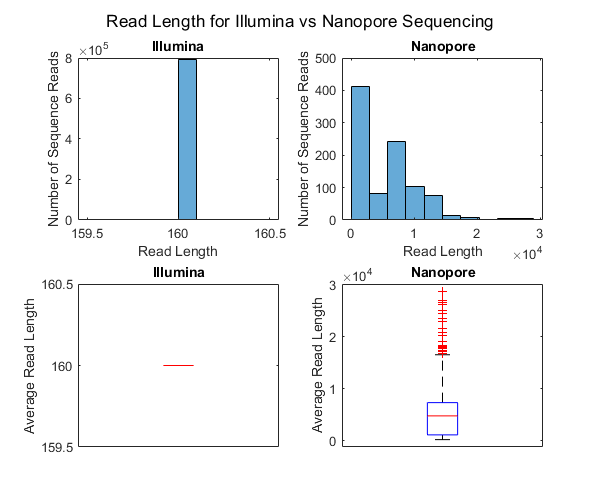

figure('Position', [0 0 600 500]), sgtitle('Read Length for Illumina vs Nanopore Sequencing')
subplot(2,2,1), histogram(readLen_ilum, 10), title('Illumina');
xlabel('Read Length'), ylabel('Number of Sequence Reads');
subplot(2,2,3), boxplot(readLen_ilum), title('Illumina'), ylabel('Average Read Length'), xticks([]);
subplot(2,2,2), histogram(readLen_nano, 10), title('Nanopore');
xlabel('Read Length'), ylabel('Number of Sequence Reads');
subplot(2,2,4), boxplot(readLen_nano), title('Nanopore'), ylabel('Average Read Length'), xticks([]);

**Caption: **The figure shows histograms (top left & right) and boxplots (bottom left & right) showing the distibution of read lengths for illumina (left panes) and nanopore (right panes) sequencing.

**Conclusion: **Illumina sequencing produces reads with a consistent read length (in this case, 160bp), while nanopore sequencing produces reads of varying lengths. The read length for nanopore is also orders of magnitude larger than the read length for Illumina sequencing. This is due to underlying differences in the sequencing technologies. Illumina sequencing kits allow for a specific number of reads per cycle (usually in the range of 150 - 300bps), while nanopore sequencing allows much larger fragments of DNA to be sequenced at a time.

#### **Second difference: Plot the nanopore and Illumina data together using histogram and box plot (caption and conclusion)**

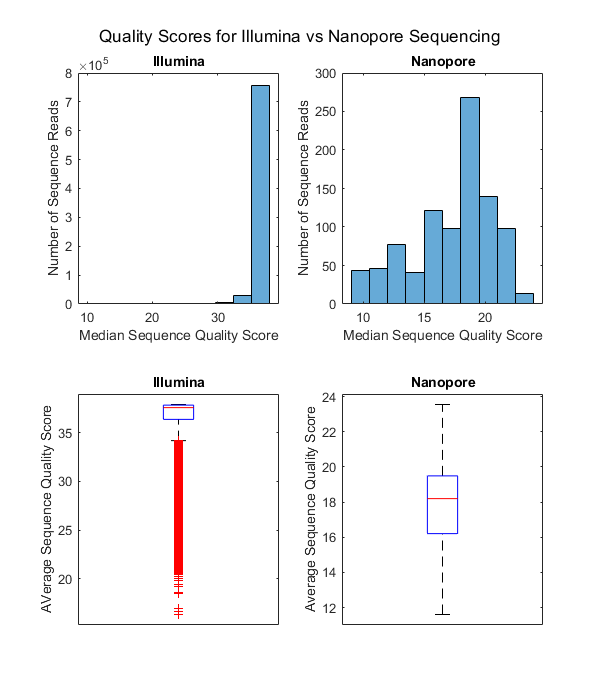

figure('Position', [0 0 600 700]), sgtitle('Quality Scores for Illumina vs Nanopore Sequencing')
subplot(2,2,1), histogram(medQS_ilum, 10), title('Illumina');
xlabel('Median Sequence Quality Score'), ylabel('Number of Sequence Reads');
subplot(2,2,3), boxplot(avgQS_ilum), title('Illumina');
ylabel('AVerage Sequence Quality Score'), xticks([]);
subplot(2,2,2), histogram(medQS_nano, 10), title('Nanopore');
xlabel('Median Sequence Quality Score'), ylabel('Number of Sequence Reads');
subplot(2,2,4), boxplot(avgQS_nano), title('Nanopore');
ylabel('Average Sequence Quality Score'), xticks([]);

**Caption: **The figure shows histograms (top left & right) and boxplots (bottom left & right) showing the distibution of quality scores for illumina (left panes) and nanopore (right panes) sequencing.

**Conclusion:** Illumina sequencing produeces higher quality reads than nanopore sequencing. The quality scores are also significantly more consistent for Illumina sequencing. With nanopore quality cores being roughly normally distributed and illumina quality scores being mostly constant at 36, with a few outliers as low as 20.

# `seqqcplot()` on Illumina Data

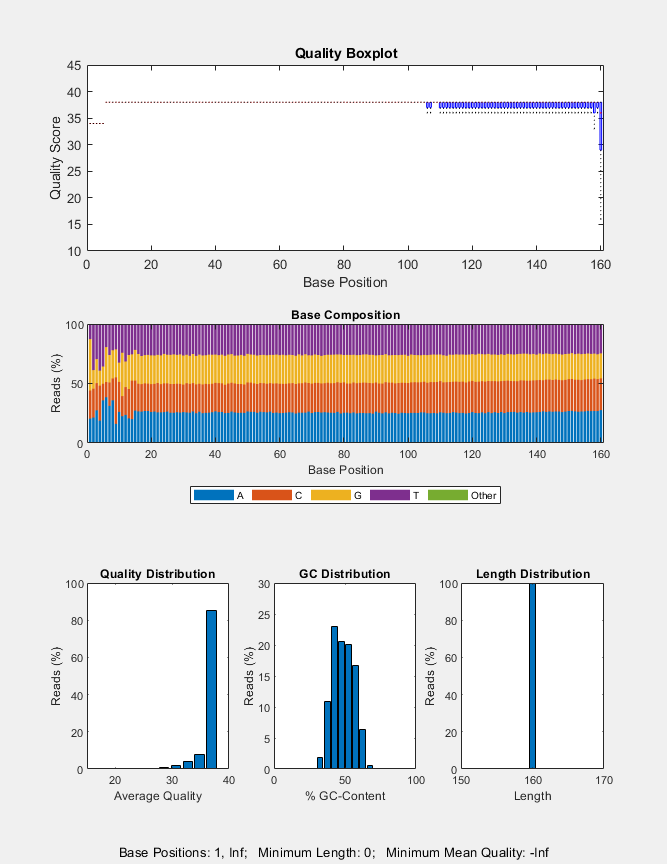

seqqcplot('lambda_illum.fastq');

%seqqcplot('lambda_nanopore.fastq')  %what happens and why?

The `seqqcplot` function does not work for nanopore sequencing data because the function currently does not support the encoding for nanopore.

# Filter Sequencing Reads

[outFile, in, out] = seqfilter('lambda_nanopore.fastq', 'Method', 'MeanQuality', 'Threshold', 15)

outFile = 1×1 cell array
    {'C:\Users\kabil\OneDrive - Drexel University\Academic\3 - Pre-Junior\1 - Fall Quarter\BMES 375\bmes375.TonyOkeke.tko35\HW8\lambda_nanopore_filtered.fastq'}

in = 797

out = 150